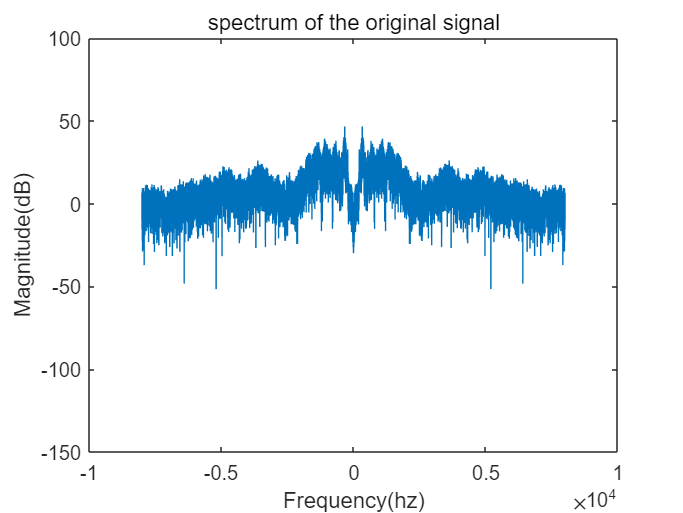

[x1, fs1] = audioread("E:\学\大二上\信号\lab\lab5\C_01_01(1).wav");
N = length(x1);
n = 0 : length(x1) - 1;
t = n / fs1;

X = fft(x1, N);

w = n*fs1/N - fs1/2;

figure(1);
X = fftshift(X);
plot(w, 20*log10(abs(X)));
% xlim([0, 52214]);
ylim([-150, 100]);
title("spectrum of the original signal");
xlabel("Frequency(hz)");
ylabel("Magnitude(dB)");

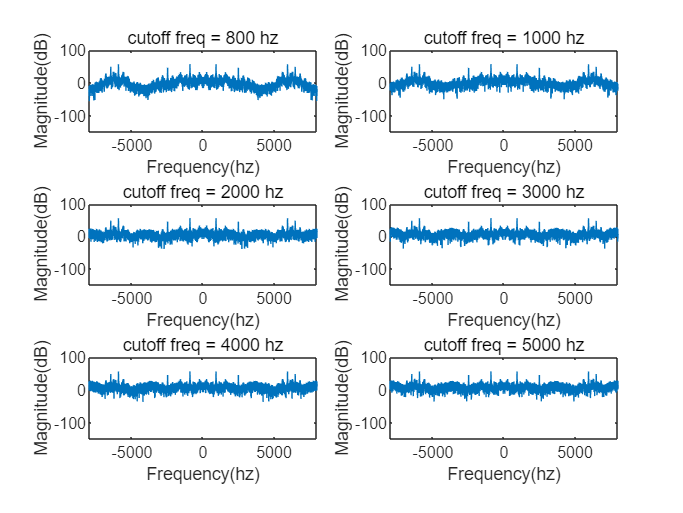

  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


  200.0000  603.5295
   1.0e+03 *
    0.6035    1.4527
   1.0e+03 *
    1.4527    3.2396
   1.0e+03 *
    3.2396    7.0000


     4


% 找带通的区间：把200和7000hz用公式转化到耳蜗的d，把耳蜗的d平均分，然后再用公式转化为f就是频带力
% （所以其实不是把200-7000hz平均分hh
close all;
figure(2);
counter = 1;
for cutoff = [800, 1000, 2000, 3000, 4000, 5000]
    [s_dot, s_dot_fft] = FilterAddNorm(x1, fs1, cutoff, 4);
    s_dot_fft = fftshift(s_dot_fft);
    plotSpectrum(counter, w, s_dot_fft, cutoff, 4);
    counter = counter + 1;
end